**Cel Ćwiczenia:**

Celem ósmych laboratoriów było zapoznanie z metodami rozwiązywania równań różniczkowych. Pomimo prostoty w wyglądzie metody Eulera nie jest ona najlepszą metodyką  ich rozwiązywania, ponieważ generuje błędy. Znacznie lepszym rozwiązaniem jest sięgnięcie w głąb Matlaba i pochylenie się szczególnie nad funkcjami solver. Nie są one wcale trudne w implementacji, ale przynoszą znacznie lepsze rezultaty niż prosta iteracja ze zmniejszaniem błędu metodą Eulera. Dodatkowo solver wygrywa czasem gdyż wraz ze zmniejszaniem kroku rośnie znacząco czas generowania odpowiedzi przez Matlaba, a tu solver nie ma takiego problemu.

**zadanie 1**

Wyprowadzenie wzoru dla metody Eulera zaczyna się od równania różniczkowego :

y′=dy/dt=f(t,y)

Rozwijając funkcję y(t) w szereg Taylora wokół punktu t, można zapisać:

 y(t+h) ≈ y(t) + h*y′(t),*

*Podstawiając y′(t)=f(t,y), otrzymuję wzór przybliżony:*

* y(t+h) ≈ y(t) + h*f(t,y),

Następnie wprowadzam oznaczenia dyskretne: tn=n*h oraz yn=y(tn). Stąd kolejny krok metody przyjmuje postać: yn+1=yn+h*f(tn,yn), co daje sposób iteracyjny na obliczanie rozwiązania. Nie jest to oczywście na tyle dokładna metoda aby wygrać z metodą analityczną y = t^2, jednak w pierwszym zadaniu poznawałem dopiero najbardziej prymitywną metodę rozwiązywania równań różniczkowych.

W tym kodzie rozwiązuję równanie różniczkowe w postaci dy/dt = 2t metodą Eulera dla różnych kroków czasowych h. Na początku definiuję symbole i ustalam kroki czasowe h oraz czas końcowy N. Tworzę pustą tablicę `y` i inicjuję jej pierwszy element jako zero. Następnie rysuję wykres używając do tego pętli for. Iteruję po wartościach `h`, a dla każdego kroku czasowego generuję wektor czasów tn od 0 do `N` z krokiem i. W pętli wewnętrznej obliczam wartość przyrostu funkcji dy na podstawie równania różniczkowego i aktualizuję y metodą Eulera. Po zakończeniu tej pętli rysuję wykres wynikowy dla bieżącego h za pomocą plot.Na koniec rysuję wykres rozwiązania analitycznego t^2 dla przedziału od 0 do N za pomocą fplot oraz dodaję stosowną legendę.

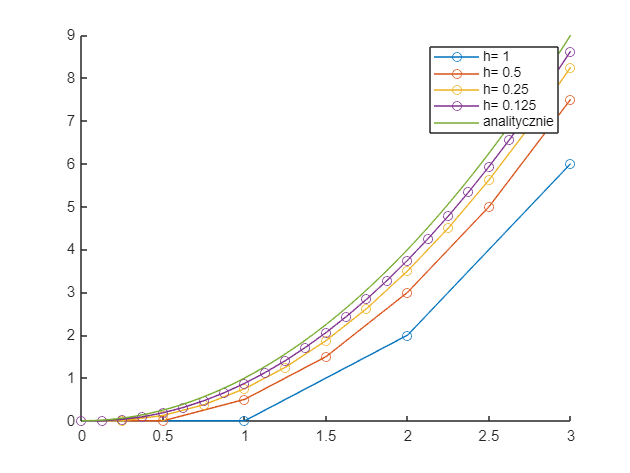

syms t
h = [1,0.5,0.25,0.125];
N = 3;
y = [];
y(1) = 0;
figure;
hold on
for i = h
    tn = 0 : i : N;
    for j = 1 : N/i
        dy = 2 * tn(j);
        y(j + 1) =  y(j) + dy * i;

    end
plot(tn,y,'o-')

end
fplot(t^2, [0,N]);
legend("h= "+num2str(h(1)),"h= "+num2str(h(2)),"h= "+num2str(h(3)),"h= "+num2str(h(4)), "analitycznie")

hold off

Jak widać, wraz ze zmniejszeniem wartości parametru „h” uzyskujemy coraz dokładniejsze wyniki. Niemniej jednak, nawet przy najmniejszym zastosowanym kroku, wykres wygenerowany nie jest na tyle dokładny aby móc w pełni zaufać tej metodzie podczas wykonywania bardziej ambitnych zadań.

Dlatego w praktyce często stosuje się bardziej zaawansowane metody, takie jak solver ode45. Solver ode45 oparty jest na metodzie Rungego-Kutty czwartego rzędu, co pozwala na uzyskanie znacznie dokładniejszych wyników przy stosunkowo niewielkim wzroście kosztów obliczeniowych. Dodatkowo ode45 automatycznie dopasowuje krok czasowy do zmienności rozwiązania, co zwiększa efektywność obliczeń. Dzięki temu solver ode45 jest w stanie lepiej radzić sobie z układami, które wymagają większej precyzji, a jednocześnie skraca czas obliczeń. W porównaniu do metody Eulera, ode45 zapewnia bardziej stabilne rozwiązania nawet w trudnych przypadkach. Właśnie dlatego ode45 jest szeroko stosowany w wielu aplikacjach numerycznych, gdzie wymagana jest zarówno dokładność, jak i wydajność obliczeniowa.

**zadanie 2 - Rozwiązanie zadania 1 za pomocą solvera**

W tym kodzie miałem za zadanie przyspieszyć proces uzgadniania krzywej dla równania różniczkowego metodą solver. Użyłem funkcji `ode45`, aby numerycznie rozwiązać równanie różniczkowe dy/dt = 2t na przedziale [0,3] z początkową wartością y(0) = 0. Następnie narysowałem wykres rozwiązania. Okazało się, że podana metoda jest znacznie dokładniejsza, nie czasochłonna oraz krótka w implementacji(oczywiście w tym wypadku funkcja również nie była skomplikowana).

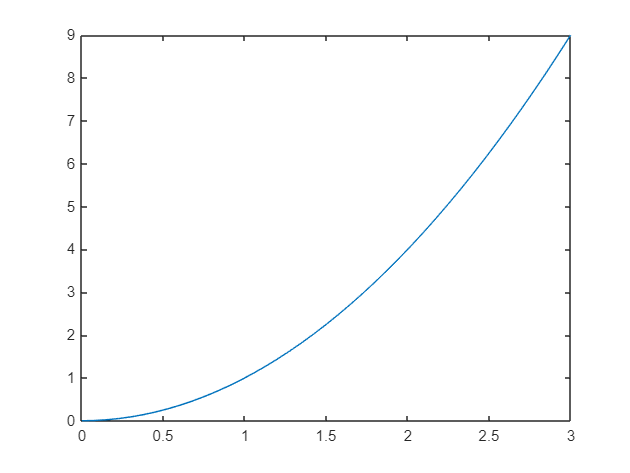

fun = @(t,y) 2*t;
[t,y] = ode45(fun,[0,3], 0);
plot(t,y);

W metodzie z użyciem solvera wyraźnie widać poprawę jakości wykresu, jest on wyraźnie dokładniejszy niż w przypadku metody Eulera oraz przypomina formę analityczną.

**Przykład**:

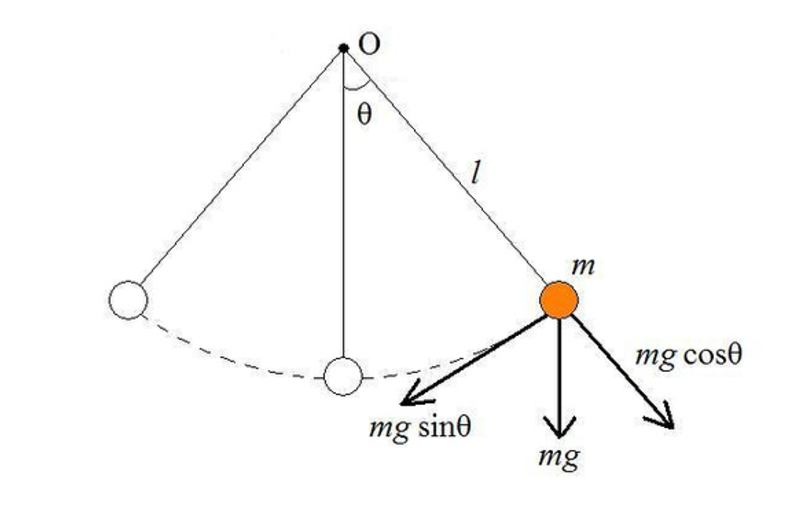

Aby przekształcić równanie ruchu wahadła z tłumieniem do przestrzeni stanów, zaczynam od równania drugiego rzędu:

θ¨ = −bmθ˙ − mgL(m − 2b)sin(θ)

Pierwszym krokiem jest wprowadzenie zmiennych stanu. Zdefiniowałem:

y1 = θ (kąt obrotu wahadła) y2 = θ˙ (prędkość kątowa)

Następnie przechodzimy do przestrzeni stanów. Równanie drugiego rzędu można zapisać jako dwa równania pierwszego rzędu:

y1˙ = y2 (zmiana kąta jest równa prędkości kątowej) y2˙ = −bm * y2 − mgL(m − 2b) * sin(y1) (zmiana prędkości kątowej jest zależna od sił tłumienia, grawitacji i siły odśrodkowej)

Zdefiniowałem funkcję opisującą ruch tłumionego wahadła, uwzględniając siłę grawitacji, długość wahadła, tłumienie i masę. Użyłem opcji odeset, aby włączyć statystyki obliczeń. Następnie rozwiązałem równanie różniczkowe dla przedziału czasowego od 0 do 25 z początkowymi warunkami kąta pi/4 i prędkości kątowej 0, korzystając z funkcji ode45. Na koniec narysowałem wykres kąta i prędkości kątowej w funkcji czasu i dodałem legendę.

function d2ydt2 = wahadlo(~,y)
g = 9.8; % m/s^2
m = 1;   % kg
L = 2;   % m
b = 0.2;
d2ydt2 = [y(2); -b/m*y(2)-m*g/L/(m-2*b)*sin(y(1))];
end

opts = odeset('stats','on');
tspan = [0 25];
y0 = [pi/4, 0];
[t,y] = ode45(@wahadlo, tspan, y0, opts);

96 successful steps
0 failed attempts
577 function evaluations


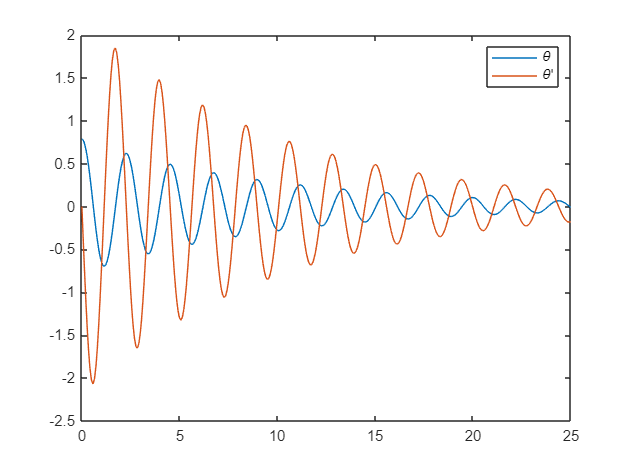

plot(t,y(:,1),t,y(:,2))
legend('\theta','\theta''')

Widać, że układ zachowuje się prawidłowo, a oscylacje harmoniczne czasowo się schodzą w sposób tłumiący.

**zadanie 3**

Zrobiłem model układu hamującego dla samolotu, który już wcześniej wykonywałem metodą bloczkową z użyciem simulinka uwzględniając masy, sprężyny i siły hamowania. Do wyznaczenia siły aerodynamicznej skorzystałem z interpolacji na podstawie prędkości. Rozwiązałem równania różniczkowe opisujące ruch przy użyciu ode45, zaczynając od początkowego stanu [0 67 0 0 0 0]. Użyłem też funkcji wyjściowej, aby zapisywać wartości przyspieszenia w zmiennej globalnej w3. Na koniec narysowałem wykresy drogi, prędkości i przyspieszenia w czasie oraz dodałem legendę.

function Dx = hamownik(~,x)
    h = 42;       %[m]
    m1=14000;
    m2 = 450.28;
    m3 = 200;
    k1 = 54700;
    k2 = 303600;
   
    % interpolacja
    wezlyF3 = [0 10 20 30 40 50 60 70 80 90 94 98 102 104 107 120];
    wartosciF3 = [833 400 160 320 520 520 660 830 1070 1600 2100 2800 4100 5000 9000 9000];
    funF3 = interp1(wezlyF3,wartosciF3,x(5),'pchip');
    Fb = funF3*x(6)^2;
    
    % zmienne stanu
    y1 = sqrt(x(1) * x(1) + h * h) - h;  
    sin_theta = x(1) / (sqrt((x(1))^2 + h^2));
    if y1 >= 2*x(3)
        Fk1 = k1*(y1 - 2 * x(3));
    else
        Fk1 = 0;
    end
    if x(3) >= x(5)
        Fk2 = k2 * (x(3) - x(5));
    else
        Fk2 = 0;
    end
    dx(1) = x(2);
    dx(2) = - 2 * Fk1 * sin_theta / m1;
    dx(3) = x(4);
    dx(4) = (2 *Fk1 - Fk2) / m2;
    dx(5) = x(6);
    dx(6) = (Fk2 - Fb) / m3;
    Dx = [dx(1);dx(2);dx(3);dx(4);dx(5);dx(6)];
end

W tym kodzie na początku definiowane są stałe, potem wykorzystywana jest interpolacja. Na samym końcu definiowane są zmienne stanu które prezentują się jak poniżej:

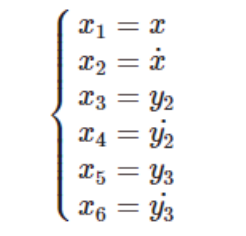  

Na samym końcu całość jest zwracana tak aby przy wywoływaniu metody solver można było do każdej zmiennej stanu sięgnąć przez odpowiedni indeks Y.

Oczywiście cały czas pozostawała kwestia jak dobrać się do zmiennej przyspieszenia. Jest to druga pochodna po prędkości, która przez to, że nie jest zmienną stanu nie będzie nigdzie wyliczana w funkcji. Do tego posłużyła funkcja pomocnicza, którą wywołuję z każdym wywołaniem funkcji solver. Dzięki użyciu zmiennej globalej w3, która zawiera punkty przyspieszenia samolotu, jestem w stanie wydrukować na samym końcu wszystkie trzy wykresy i sprowadzić problem hamownika samolotów do tego samego wykresu co na poprzenich laboratoriach.

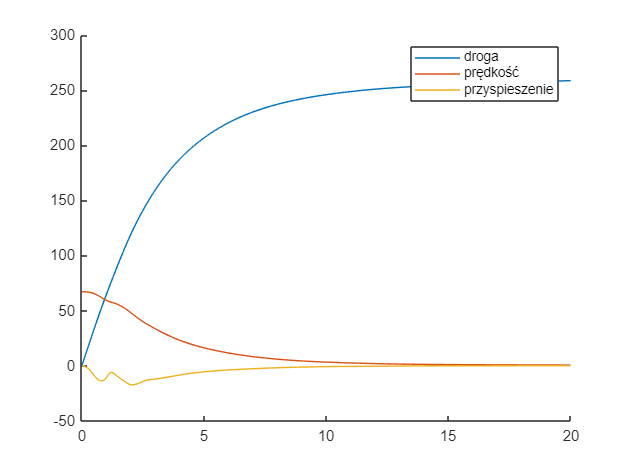

global w3

function status = hamownik_out(~,x,flag)

global w3
h = 42;       %[m]
k1 = 54.7e3;  %[N/m]
m1 = 14000;   %[kg]

if strcmp(flag,'init')
    w3 = 0;
elseif isempty(flag)
    y1 = sqrt(x(1)^2+h^2)-h;
    sin_theta = x(1)/(h+y1);
    
    if y1 >= 2*x(3)
        Fk1 = k1*(y1-2*x(3));
    else
        Fk1 = 0;
    end
    
    w3 = [w3;-2*Fk1*sin_theta/m1];
end
status = 0;
end

options = odeset('OutputFcn',@hamownik_out,'Refine',1);
figure;
hold on
[T,Y] = ode45(@hamownik,[0 20],[0 67 0 0 0 0],options);
plot(T,Y(:,1),T,Y(:,2))
plot(T,w3)

legend('droga','prędkość','przyspieszenie')
hold off

Uzyskane wykresy w pełni odpowiadają tym, które uzyskałem na zajęciach z Modelowania urządzenia hamującego samoloty. Teraz wystarczyło tylko całość przerzucić do solvera i wszystko jest w najlepszym porządku. Do wykresu dodałem legendę także widać jak od początku samolot hamował osiągając maksymalną drogę równą około 250 m.

**Wnioski:**

Metoda Eulera, choć prosta i szybka, nie zapewnia dużej dokładności, szczególnie w przypadku bardziej złożonych układów. Zmniejszanie kroku czasowego może poprawić precyzję wyników, jednak wiąże się to z wydłużeniem czasu obliczeń. Z kolei solver ode45, oparty na metodzie Rungego-Kutty czwartego rzędu, jest bardziej dokładny, a także automatycznie dopasowuje krok czasowy, co czyni go bardziej efektywnym w wielu przypadkach. 